# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1.a:**

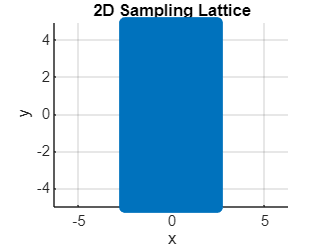

a=6;
b=2;
N=200; %We will have (N+1)x(N+1) samples

[m,n]= meshgrid(-floor(N/2):floor(N/2)-1);

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

V=[1/40,0;0,1/20];

x = V(1,1)*m + V(1,2)*n;
y = V(2,1)*m + V(2,2)*n;

psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
scatter(x(:), y(:), 50, 'filled');  % 50 = marker size
axis equal;
xlabel('x'); ylabel('y');
title('2D Sampling Lattice');
grid on;

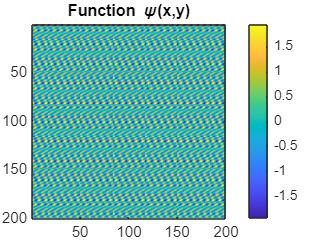


%2D plot of the sampled signal (psi)
imagesc(psi_s);
colorbar;
axis equal tight;  % optional, keeps aspect ratio correct
title('Function \psi(x,y)');

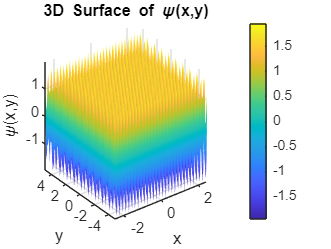


%3D plot of the sampled signal (psi)
figure;
surf(x, y, psi_s);        % create 3D surface
shading interp;            % smooth shading
colorbar;                  % show color scale
axis tight;                % fit axes tightly
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');

### **Task 1.b:**

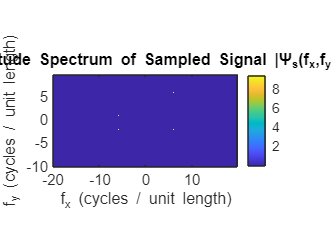

% --- 2D FFT of the sampled signal ---
Psi = fftshift(fft2(psi_s));

% Magnitude spectrum
Psi_mag = abs(Psi);

% log scale for better visibility
Psi_log = log(1 + Psi_mag);

Nx = size(psi_s, 2);   % along x (columns)
Ny = size(psi_s, 1);   % along y (rows)

dx = V(1,1);   % = 1/40
dy = V(2,2);   % = 1/20

fx = (-Nx/2:Nx/2-1)/(Nx*dx);
fy = (-Ny/2:Ny/2-1)/(Ny*dy);

figure;
imagesc(fx, fy, Psi_log);
axis xy;
axis equal tight;
colorbar;

xlabel('f_x (cycles / unit length)');
ylabel('f_y (cycles / unit length)');
title('Magnitude Spectrum of Sampled Signal |\Psi_s(f_x,f_y)|');

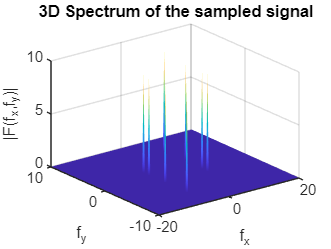


figure;
surf(fx, fy, Psi_log);
shading interp;
xlabel('f_x'); ylabel('f_y'); zlabel('|F(f_x,f_y)|');
title('3D Spectrum of the sampled signal');

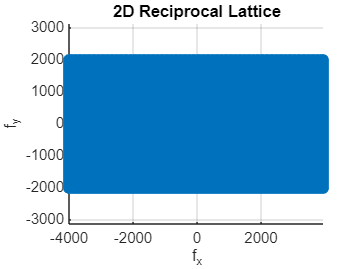

%reciprocal latice
U = inv(V');
[m,n]= meshgrid(-N/2:N/2-1, -N/2:N/2-1);
f_x = U(1,1)*m + U(1,2)*n;
f_y = U(2,1)*m + U(2,2)*n;

%2D plot of the reciprocal lattice grid.
figure;
scatter(f_x(:), f_y(:), 50, 'filled');  % 50 = marker size
axis equal;
xlabel('f_x'); ylabel('f_y');
title('2D Reciprocal Lattice');
grid on;

### **Task 2.a:**

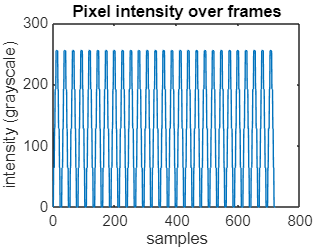

path = "\task2_orig120fps.avi";
v = VideoReader(path);

c = 20;
d = 30;

x = 5*c;
y = 5*d;

pixel_values = [];

while hasFrame(v)
    frame = readFrame(v,'native');
    pixel_values(end+1) = double(frame.cdata(y,x)); % y: eix vertical (files), x:eix horitzontal (columnes)
end

figure;
plot(pixel_values)
xlabel('samples'); ylabel('intensity (grayscale)');
title('Pixel intensity over frames');


F_pixel = fft(pixel_values)

F_pixel = 1.0e+04 *

   9.1998 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0440 - 0.0200i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0004 - 0.0003i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -4.1660 - 2.2060i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 - 0.0008i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0431 - 0.1062i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


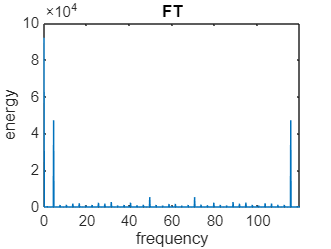

% Magnitude spectrum
F_mag = abs(F_pixel);

N = length(pixel_values);
Fs = v.FrameRate;
f = (0:N-1)*(Fs/N);

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title('FT');


clear v;